clear
clc

load('hall.mat');
[h,w] = size(hall_gray,[1 2]);

方法1：用信息位逐一替换所有量化后DCT系数最低位，再进行熵编码

info = int32(randi([0 1],h,w)); % 生成随机的测试信息
[ACstream,DCstream,h,w] = DCTconceal1(hall_gray,info); % 信息隐藏
infoRtv = DCTretrieve1(ACstream,DCstream,h,w); % 信息提取

获取信息隐藏图像

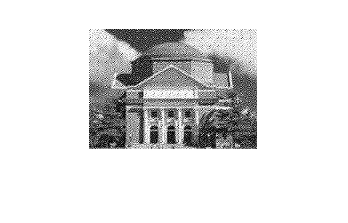

ImageConceal = JpegDecoder(DCstream,ACstream,h,w);
imshow(ImageConceal);

计算PSNR

MSE = sum((ImageConceal-hall_gray).^2,'all')/h/w;
PSNR = 10 * log10(255^2/MSE);

计算压缩率

compressrate = 8*h*w/(length(ACstream)+length(DCstream));

评估信息还原的准确率

ErrorMtx = bitxor(info,infoRtv); % 按位异或得错误
fidelity = 1-sum(ErrorMtx,"all")/h/w; % 还原率

PSNR = 28.1473, 28.1461, 28.1667, 28.1531, 28.1576

compressrate = 2.8616, 2.8567, 2.8580, 2.8751, 2.8730

fidelity = 1, 1, 1, 1, 1